# **SISTEMAS DE CONTROL **

# 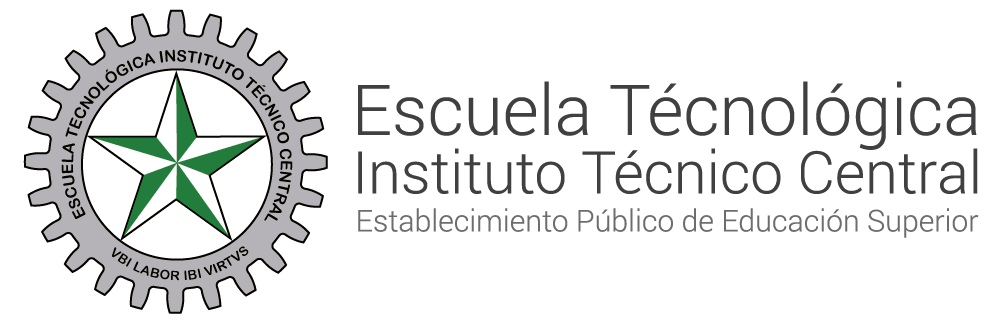

# **Técnicas de Discretización**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO 

**OBJETIVO: ** Encontrar mediante técnicas de discretización una función de transferencia que represente aproximadamente las mismas características de la función de transferencia continua.

## Equivalencias Discretas

son métodos para diseñar controladores digitales que aproximan el comportamiento de sistemas continuos. Estos métodos permiten convertir modelos analógicos (en tiempo continuo) a representaciones discretas, manteniendo características clave como la estabilidad, la respuesta en frecuencia o la dinámica temporal. Su objetivo es facilitar la implementación de controladores en sistemas digitales, como microprocesadores.

Por ejemplo el sistema de primer orde:


$$G\left(s\right)=\frac{a}{s+a}$$


asumiendo a=2 y Ts=0.1

clear all
clc
syms s
Ts=0.1;
a=2;
numerador = [a];   
denominador = [1 a];  
sys=tf(numerador,denominador)


sys =
 
    2
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


# Técnica de discretización  Euler hacia adelante

La **equivalencia de discretización mediante el método de Euler hacia adelante** (también llamado *Forward Euler*) es una técnica para convertir un sistema continuo en tiempo discreto, aproximando la derivada de una señal mediante una diferencia finita hacia adelante. 

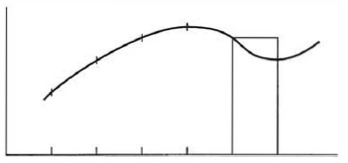

$x^{\prime } \left(\mathrm{kT}\right)\approx \frac{x\left\lbrack \left(k+1\right)T\right\rbrack -x\left\lbrack \mathrm{kT}\right\rbrack }{T}$�


$$s\to \frac{z-1}{T}$$


Ejemplo. Para la siguiente función de transferencia en el dominio de s con a=2 y Ts=0.1:


$$G\left(s\right)=\frac{a}{s+a}$$


reemplazando s por el equivalente z de euler hacia adelante, resulta:


$$G\left(z\right)=\frac{a}{\left(\frac{z-1}{T}\right)+a}$$



$$G\left(z\right)=\frac{a}{\frac{\left(z-1\right)}{T}+a}$$



$$G\left(z\right)=\frac{2}{\frac{\left(z-1\right)}{0\ldotp 1}+2}$$



$$G\left(z\right)=\frac{0\ldotp 2}{z-1+0\ldotp 2}$$



$$G\left(z\right)=\frac{0\ldotp 2}{z-0\ldotp 8}$$


z=tf("z",Ts);
a=2;
sys_eule_f = tf(a/(((z-1)/Ts)+a),Ts)


sys_eule_f =
 
    0.2
  -------
  z - 0.8
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


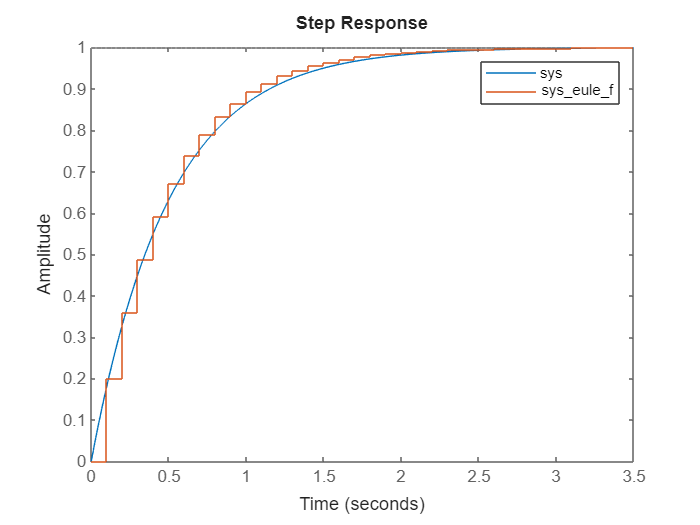

step(sys)
hold on
step(sys_eule_f)
legend()
hold off

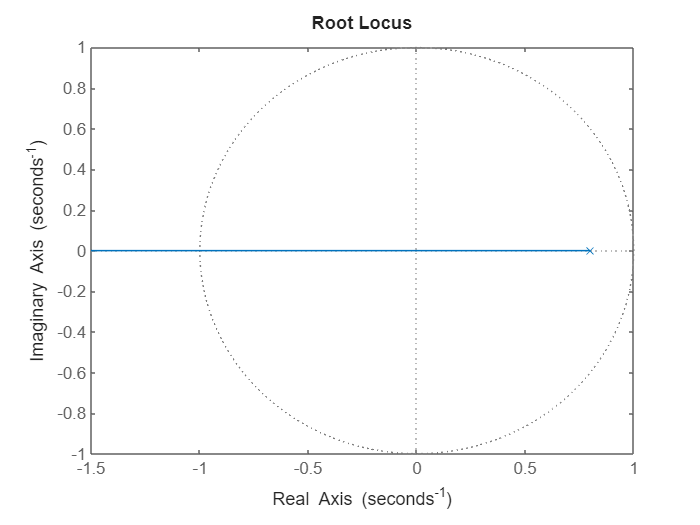

rlocus(sys_eule_f)

# Técnica de discretización  Euler hacia atrás

La **equivalencia de discretización mediante el método de Euler hacia átras** (también llamado Back*ward Euler*) es una técnica para convertir un sistema continuo en tiempo discreto, aproximando la derivada de una señal mediante una diferencia finita hacia átras. 


$$x^{\prime } \left(T\left(K+1\right)\right)\approx \frac{x\left\lbrack \left(k+1\right)T\right\rbrack -x\left\lbrack \mathrm{kT}\right\rbrack }{T}$$


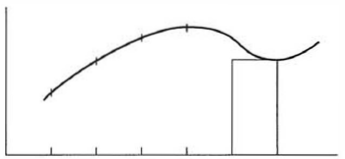


$$s\to \frac{z-1}{T\;z}$$


Ejemplo. Para la siguiente función de transferencia en el dominio de s con a=2 y Ts=0.1:


$$G\left(s\right)=\frac{a}{s+a}$$


reemplazando s por el equivalente z de euler hacia átras, resulta:


$$G\left(z\right)=\frac{a}{\left(\frac{z-1}{\mathrm{Tz}}\right)+a}$$



$$G\left(z\right)=\frac{2}{\left(\frac{z-1}{0\ldotp 1z}\right)+2}$$



$$G\left(z\right)=\frac{2}{\left(\frac{z-1+0\ldotp 2z}{0\ldotp 1z}\right)}$$



$$G\left(z\right)=\frac{0\ldotp 2z}{1\ldotp 2z-1}$$


z=tf("z",Ts);
a=2;
sys_euler_B = tf(a/(((z-1)/(z*Ts))+a),Ts)


sys_euler_B =
 
    0.2 z
  ---------
  1.2 z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


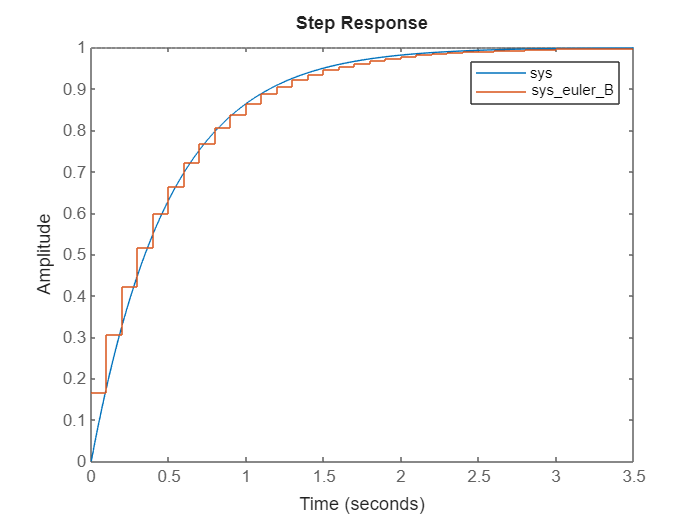

step(sys)
hold on
step(sys_euler_B)
legend()
hold off

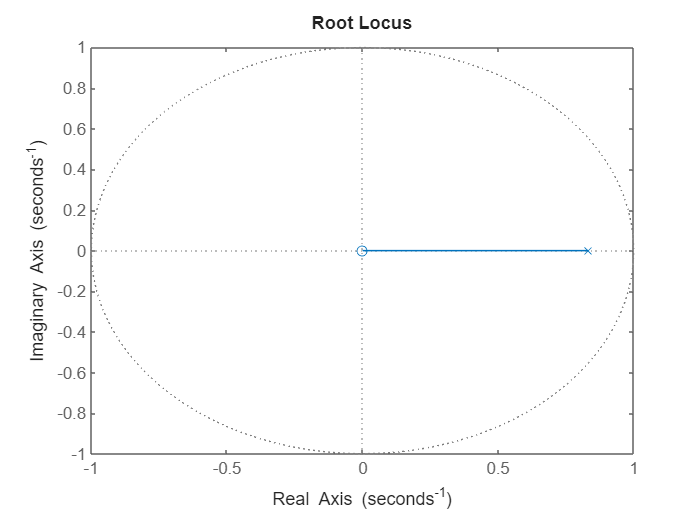

rlocus(sys_euler_B)

# Tecnica de discretización de Tustin (Bilineal o Trapezoide)

Aproximación del área por el rectángulo formado por el promedio de los rectángulos generados anteriormente.

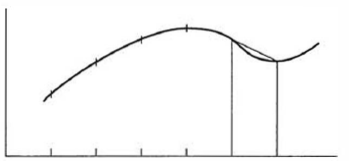


$$s\to \frac{2}{T}\frac{z-1}{z+1}$$


reemplazando s en 


$$G\left(s\right)=\frac{a}{s+a}$$


resulta:


$$G\left(z\right)=\frac{a}{\left(\frac{2}{T}\;\frac{z-1}{z+1}\right)+a}$$



$$G\left(z\right)=\frac{2}{\left(\frac{2}{0\ldotp 1}*\frac{z-1}{z+1}\right)+2}$$



$$G\left(z\right)=\frac{2}{\left(\frac{20z-20}{z+1}\right)+\frac{2z+2}{z+1}}$$



$$G\left(z\right)=\frac{2}{\left(\;\frac{20z-20+2z+2}{z+1}\right)}$$



$$G\left(z\right)=\frac{2z+2}{22z-18}$$



$$G\left(z\right)=\frac{\ldotp 0909z+0\ldotp 09090}{z-0\ldotp 8181}$$


sys_z_B = c2d(tf(numerador, denominador), Ts, 'tustin')


sys_z_B =
 
  0.09091 z + 0.09091
  -------------------
      z - 0.8182
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


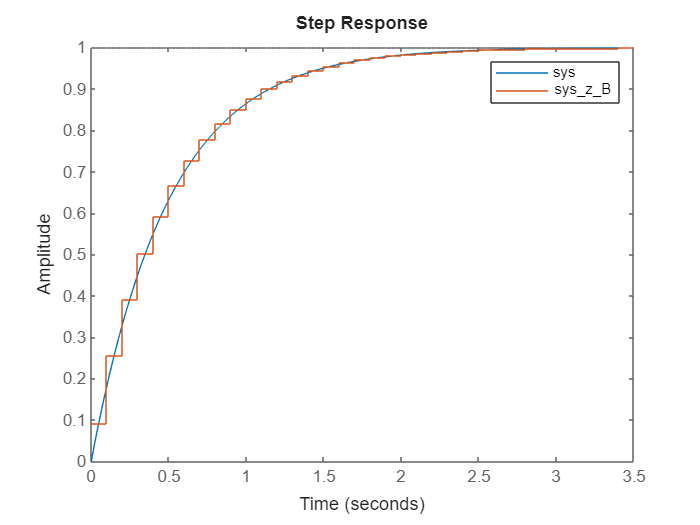

step(sys)
legend()
hold on
step(sys_z_B)
hold off

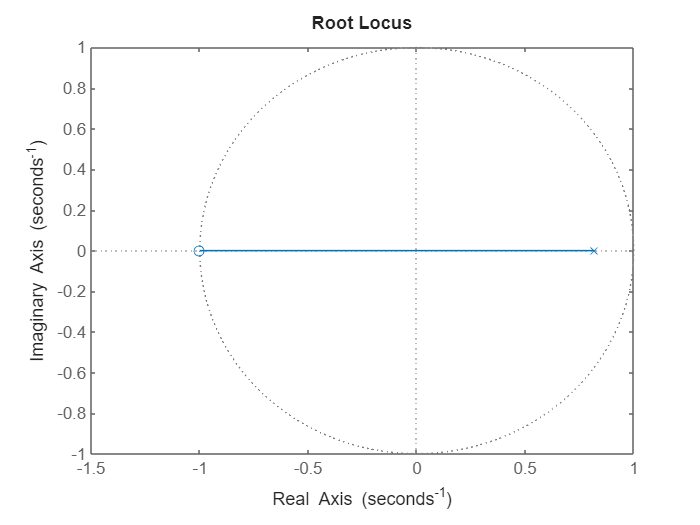

rlocus(sys_z_B)

# Tecnica de discretización por Retenedor de orden cero.

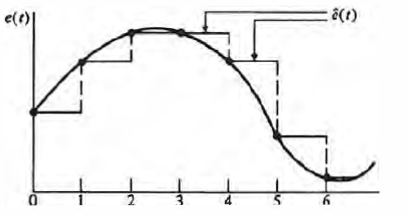

sys_zoh = c2d(tf(numerador, denominador), Ts, 'zoh')


sys_zoh =
 
    0.1813
  ----------
  z - 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


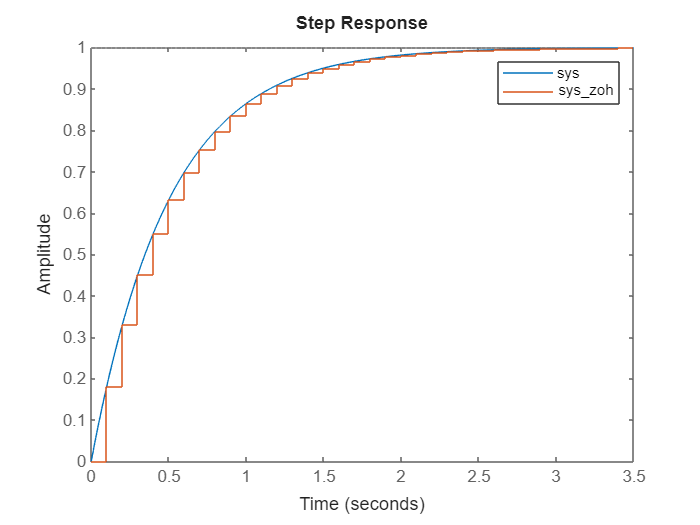

step(sys)
legend()
hold on
step(sys_zoh)
hold off
legend

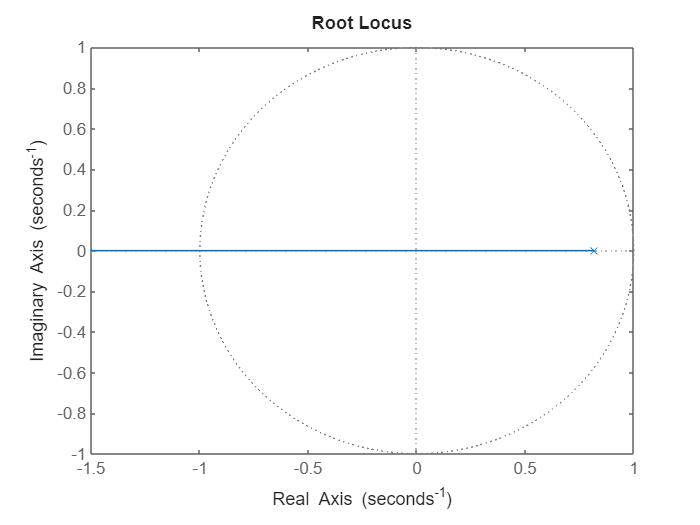

rlocus(sys_zoh)

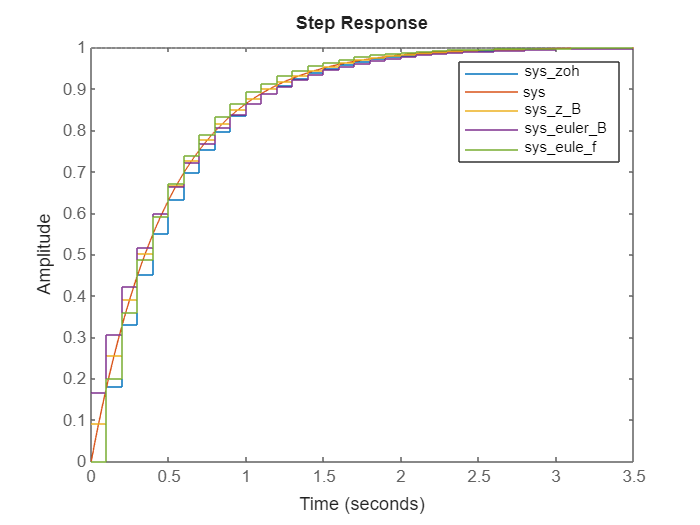


step(sys_zoh)
hold on
legend()
step(sys)
step(sys_z_B)
step(sys_euler_B)
step(sys_eule_f)
hold off

## Conclusión-Comparación